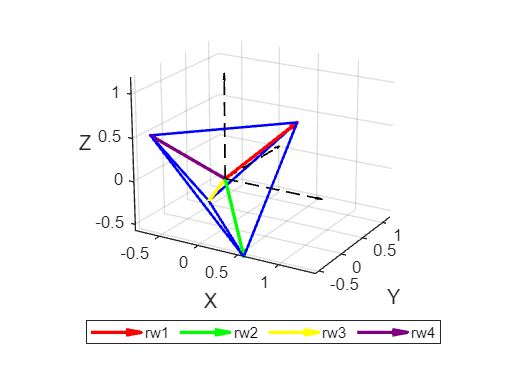

% plot_tetrahedral_rw_axes.m
clear; clc; close all;

% 1) Задаём вершины правильного тетраэдра
% Координаты можно взять так, чтобы центр в начале координат:
a = 1;  % масштаб
v = [  a,  a,  a;
       a, -a, -a;
      -a,  a, -a;
      -a, -a,  a ] / sqrt(3);  % нормируем расстояние до центра

% 2) Рисуем рёбра тетраэдра
faces = [1 2; 1 3; 1 4; 2 3; 2 4; 3 4];
figure('Color','w'); hold on; grid on; axis equal;
for i = 1:size(faces,1)
    P = v(faces(i,:),:);
    plot3(P(:,1), P(:,2), P(:,3), 'b-', 'LineWidth', 1.5);
end

% 3) Рисуем стрелки осей маховиков (из центра к вершинам)
colors = [ 1 0 0;    ... % red
         0 1 0;    ... % green
         1 1 0;    ... % yellow
         0.5 0 0.5 ]; % purple
h_rw = gobjects(4,1); % массив хэндлов
for i = 1:4
    h_rw(i) = quiver3(0,0,0, v(i,1), v(i,2), v(i,3), ...
        0, 'Color',colors(i,:), 'LineWidth',2, 'MaxHeadSize',0.5);
end

% 4) Добавим пунктирные координатные оси
axis_len = 1.2;
quiver3(0,0,0, axis_len,0,0, 0,'k--','LineWidth',1);  % X
quiver3(0,0,0, 0,axis_len,0, 0,'k--','LineWidth',1);  % Y
quiver3(0,0,0, 0,0,axis_len, 0,'k--','LineWidth',1);  % Z
legend(h_rw, {'rw1','rw2','rw3','rw4'}, 'Location','southoutside','Orientation','horizontal');
% 5) Оформление
xlabel('X','FontSize',12);
ylabel('Y','FontSize',12);
% legend(h, {'','pitch','roll'});
zlabel('Z','FontSize',12, 'Rotation',0);

view(30,20);
camproj('perspective');